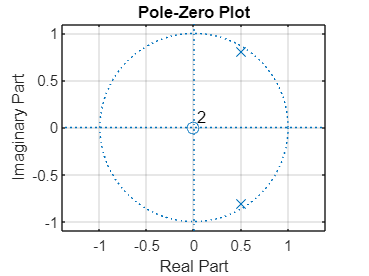

%Find the Coefficients of the given LTI system 
clc; clear all; close all;
b=1;
a=[1,-1,0.9];
%Plot the Zeros and Poles on Z plane
zplane(b,a)
grid;

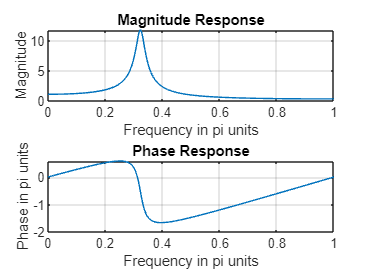

figure;
% Find the Magnitude and Phase response of LTI system
w=(0:1:500)*pi/500;
H=freqz(b,a,w);
m=abs(H);
p=angle(H);
subplot(2,1,1);
plot(w/pi,m);
xlabel('Frequency in pi units');
ylabel('Magnitude');
title('Magnitude Response');
grid;
subplot(2,1,2);
plot(w/pi,p);
xlabel('Frequency in pi units');
ylabel('Phase in pi units');
title('Phase Response');
grid;

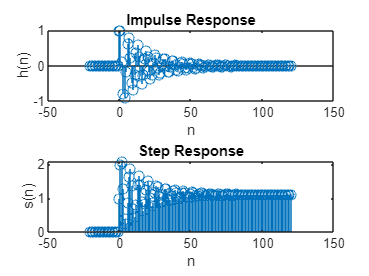

figure;
% Impulse response 
x=impseq(0,-20,120);
n=-20:120;
h=filter(b,a,x);
subplot(2,1,1);stem(n,h);
title('Impulse Response');
xlabel('n');
ylabel('h(n)');
% Step response
x=stepseq(0,-20,120);
n=-20:120;
s=filter(b,a,x);
subplot(2,1,2);stem(n,s);
title('Step Response');
xlabel('n');
ylabel('s(n)');

% Step sequence 

function [x,n] = stepseq(n0,n1,n2)
n=n1:n2; % Actual computation
x=(n-n0)>=0;
end
% Impulse sequence 
function [x, n]=impseq(n0,n1,n2)
n = n1:n2;
x = (n-n0)==0;
end
